### Ładowanie pliku obrazu

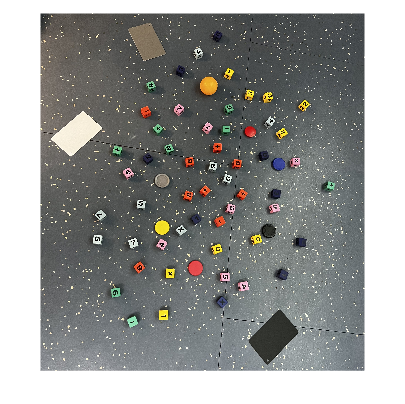

RGB = imread('sample.jpg');
imshow(RGB);

### Separacja kanału barwy

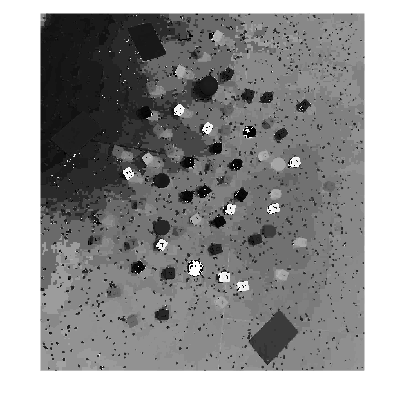

HSV = rgb2hsv(RGB);
H = HSV(:,:,1);
imshow(H);

### Wizualizacja kanału barwy

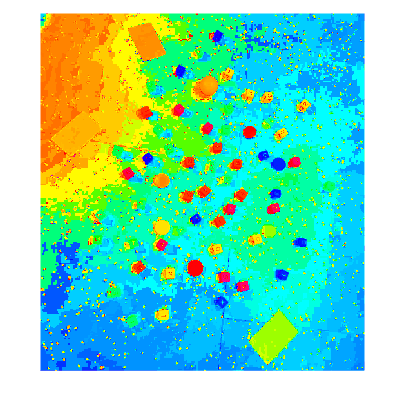

imshow(H);
colormap('hsv');

### Progowanie kolorów

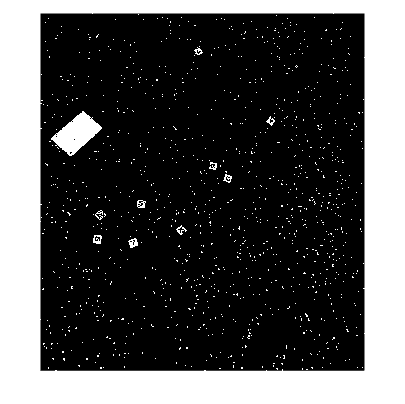

thresholds = dictionary( ...
    "red", {[0.992, 0.071; 0.375, 1.000; 0.725, 1.000]}, ...
    "yellow", {[0.144, 0.233; 0.442, 1.000; 0.872, 1.000]}, ...
    "green", {[0.205, 0.433; 0.165, 1.000; 0.235, 1.000]}, ...
    "blue", {[0.519, 0.730; 0.222, 0.785; 0.126, 0.717]}, ...
    "magenta", {[0.828, 0.968; 0.000, 0.696; 0.587, 1.000]}, ...
    "orange", {[0.086, 0.118; 0.744, 0.878; 0.876, 1.000]}, ...
    "gray", {[0.058, 0.127; 0.157, 0.348; 0.465, 0.665]}, ...
    "black", {[0.165, 0.293; 0.065, 0.217; 0.122, 0.243]}, ...
    "white", {[0.105, 0.517; 0.000, 0.233; 0.832, 1.000]} ...
);

colors = keys(thresholds);


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Create mask based on chosen histogram thresholds
masks = dictionary();
for color_index = 1:length(colors)
    color = colors(color_index);
    value = thresholds(color);
    value = value{1};
    channel1Min = value(1, 1);
    channel1Max = value(1, 2);
    channel2Min = value(2, 1);
    channel2Max = value(2, 2);
    channel3Min = value(3, 1);
    channel3Max = value(3, 2);
    if (channel1Min <= channel1Max)
    mask = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
    masks(color) = {mask};
    else 
    mask = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
    masks(color) = {mask};
    end
end

imshow(mask);

### Poprawa maski

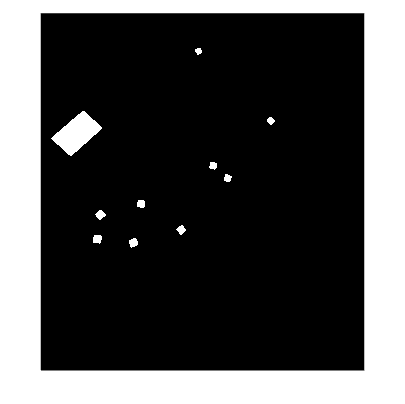

for color_index = 1:length(colors)
    color = colors(color_index);
    BW = masks(color);
    BW = BW{1};

    % Close mask
    radius = 3;
    decomposition = 0;
    se = strel('disk', radius, decomposition);
    BW = imclose(BW, se);
    
    % Fill holes
    BW = imfill(BW, 'holes');

    % Open mask
    radius = 11;
    decomposition = 0;
    se = strel('disk', radius, decomposition);
    BW = imopen(BW, se);

    masks(color) = {BW};
    imshow(BW);
end

### Filtracja regionów po rozmiarze i odczytanie średniej barwy

out = RGB;
for color_index = 1:length(colors)
    colorname = colors(color_index);
    BW = masks(colorname);
    BW = BW{1};
    props = regionprops(BW, {'Area', 'Eccentricity', 'EquivDiameter', 'BoundingBox', 'PixelIdxList', 'Centroid', 'Circularity'});
    for i=1:size(props, 1)
        if props(i).Area > 800
            % avg_h = mean(H(props(i).PixelIdxList));
            % color_avg = hsv2rgb([avg_h, 1, 1]) * 255;
            if strcmp(colorname, 'orange')
                color = [255 127 80];
            elseif strcmp(colorname, 'gray')
                color = [150 150 150];
            else
                color = validatecolor(colorname) * 255;
            end

            if props(i).Circularity > 0.92
                shape = "circle";
                pos = [props(i).Centroid, props(i).EquivDiameter/2];
            else
                shape = "rectangle";
                pos = props(i).BoundingBox;
            end
            % label = sprintf("%.3f", avg_h);
            label = sprintf("%s %s", colorname, shape);
            label
            props(i)
            out = insertObjectAnnotation(out, shape, pos, label, "Color", color) ;
        end
    end
end

label = "red rectangle"

ans = struct with fields:
             Area: 5570
         Centroid: [872.2424 2.2416e+03]
      BoundingBox: [824.5000 2.1925e+03 96 98]
     Eccentricity: 0.3427
      Circularity: 0.8761
    EquivDiameter: 84.2137
     PixelIdxList: [5570×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 4795
         Centroid: [924.6048 860.8874]
      BoundingBox: [884.5000 820.5000 86 84]
     Eccentricity: 0.5119
      Circularity: 0.8672
    EquivDiameter: 78.1357
     PixelIdxList: [4795×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 4569
         Centroid: [1.3060e+03 1.6063e+03]
      BoundingBox: [1.2655e+03 1.5665e+03 81 79]
     Eccentricity: 0.2994
      Circularity: 0.8731
    EquivDiameter: 76.2721
     PixelIdxList: [4569×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 4182
         Centroid: [1.3165e+03 1.3042e+03]
      BoundingBox: [1.2765e+03 1.2705e+03 77 69]
     Eccentricity: 0.4182
      Circularity: 0.8817
    EquivDiameter: 72.9705
     PixelIdxList: [4182×1 double]


label = "red circle"

ans = struct with fields:
             Area: 12756
         Centroid: [1.3686e+03 2.2488e+03]
      BoundingBox: [1.3035e+03 2.1845e+03 128 129]
     Eccentricity: 0.2094
      Circularity: 0.9736
    EquivDiameter: 127.4419
     PixelIdxList: [12756×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 4467
         Centroid: [1.4546e+03 1.5639e+03]
      BoundingBox: [1.4085e+03 1.5215e+03 91 86]
     Eccentricity: 0.4151
      Circularity: 0.8249
    EquivDiameter: 75.4159
     PixelIdxList: [4467×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 4004
         Centroid: [1.5637e+03 1.1752e+03]
      BoundingBox: [1.5245e+03 1.1435e+03 74 63]
     Eccentricity: 0.5393
      Circularity: 0.8964
    EquivDiameter: 71.4006
     PixelIdxList: [4004×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 5673
         Centroid: [1.5835e+03 1.8366e+03]
      BoundingBox: [1.5355e+03 1.7905e+03 97 91]
     Eccentricity: 0.4717
      Circularity: 0.8971
    EquivDiameter: 84.9888
     PixelIdxList: [5673×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 3971
         Centroid: [1.7404e+03 1.3215e+03]
      BoundingBox: [1.7065e+03 1.2875e+03 68 68]
     Eccentricity: 0.4193
      Circularity: 0.8950
    EquivDiameter: 71.1058
     PixelIdxList: [3971×1 double]


label = "red rectangle"

ans = struct with fields:
             Area: 3982
         Centroid: [1.7856e+03 1.5937e+03]
      BoundingBox: [1.7455e+03 1.5535e+03 80 81]
     Eccentricity: 0.3831
      Circularity: 0.8907
    EquivDiameter: 71.2042
     PixelIdxList: [3982×1 double]


label = "red circle"

ans = struct with fields:
             Area: 6459
         Centroid: [1.8520e+03 1.0447e+03]
      BoundingBox: [1.8045e+03 1.0005e+03 96 88]
     Eccentricity: 0.4913
      Circularity: 0.9740
    EquivDiameter: 90.6855
     PixelIdxList: [6459×1 double]


label = "yellow circle"

ans = struct with fields:
             Area: 12437
         Centroid: [1.0740e+03 1.8903e+03]
      BoundingBox: [1.0105e+03 1.8285e+03 127 124]
     Eccentricity: 0.2282
      Circularity: 0.9869
    EquivDiameter: 125.8383
     PixelIdxList: [12437×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 6039
         Centroid: [1.0874e+03 2.6641e+03]
      BoundingBox: [1.0485e+03 2.6225e+03 78 83]
     Eccentricity: 0.3937
      Circularity: 0.8886
    EquivDiameter: 87.6875
     PixelIdxList: [6039×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 5510
         Centroid: [1.1445e+03 2.2957e+03]
      BoundingBox: [1.1065e+03 2.2565e+03 75 78]
     Eccentricity: 0.3045
      Circularity: 0.8946
    EquivDiameter: 83.7589
     PixelIdxList: [5510×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 4726
         Centroid: [1.5630e+03 2.0780e+03]
      BoundingBox: [1.5215e+03 2.0365e+03 83 83]
     Eccentricity: 0.3043
      Circularity: 0.8900
    EquivDiameter: 77.5715
     PixelIdxList: [4726×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 3061
         Centroid: [1.6695e+03 516.8902]
      BoundingBox: [1.6335e+03 483.5000 71 67]
     Eccentricity: 0.5391
      Circularity: 0.9000
    EquivDiameter: 62.4290
     PixelIdxList: [3061×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 2980
         Centroid: [1.8530e+03 705.3644]
      BoundingBox: [1.8205e+03 674.5000 65 62]
     Eccentricity: 0.5155
      Circularity: 0.8728
    EquivDiameter: 61.5975
     PixelIdxList: [2980×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 4318
         Centroid: [1.9156e+03 1.9918e+03]
      BoundingBox: [1.8775e+03 1.9535e+03 77 77]
     Eccentricity: 0.4318
      Circularity: 0.8785
    EquivDiameter: 74.1475
     PixelIdxList: [4318×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 3100
         Centroid: [2.0161e+03 726.7203]
      BoundingBox: [1.9845e+03 697.5000 64 58]
     Eccentricity: 0.4607
      Circularity: 0.9034
    EquivDiameter: 62.8255
     PixelIdxList: [3100×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 3379
         Centroid: [2.1423e+03 1.0486e+03]
      BoundingBox: [2.1045e+03 1.0125e+03 76 72]
     Eccentricity: 0.4808
      Circularity: 0.8921
    EquivDiameter: 65.5917
     PixelIdxList: [3379×1 double]


label = "yellow rectangle"

ans = struct with fields:
             Area: 2925
         Centroid: [2.3383e+03 798.2116]
      BoundingBox: [2.3035e+03 764.5000 70 68]
     Eccentricity: 0.5618
      Circularity: 0.8990
    EquivDiameter: 61.0264
     PixelIdxList: [2925×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 6329
         Centroid: [663.6355 2.4651e+03]
      BoundingBox: [620.5000 2.4205e+03 87 90]
     Eccentricity: 0.3809
      Circularity: 0.8140
    EquivDiameter: 89.7682
     PixelIdxList: [6329×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 7131
         Centroid: [678.8323 1.2175e+03]
      BoundingBox: [630.5000 1.1655e+03 97 104]
     Eccentricity: 0.4301
      Circularity: 0.8275
    EquivDiameter: 95.2863
     PixelIdxList: [7131×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 6721
         Centroid: [812.0830 2.7228e+03]
      BoundingBox: [761.5000 2.6715e+03 100 103]
     Eccentricity: 0.3831
      Circularity: 0.8646
    EquivDiameter: 92.5064
     PixelIdxList: [6721×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 6583
         Centroid: [974.1525 646.8683]
      BoundingBox: [931.5000 595.5000 86 105]
     Eccentricity: 0.5404
      Circularity: 0.8776
    EquivDiameter: 91.5518
     PixelIdxList: [6583×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 6455
         Centroid: [1.0361e+03 1.0295e+03]
      BoundingBox: [990.5000 975.5000 92 109]
     Eccentricity: 0.4980
      Circularity: 0.8813
    EquivDiameter: 90.6574
     PixelIdxList: [6455×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 5276
         Centroid: [1.1338e+03 1.1946e+03]
      BoundingBox: [1.0895e+03 1.1505e+03 90 101]
     Eccentricity: 0.4520
      Circularity: 0.6858
    EquivDiameter: 81.9610
     PixelIdxList: [5276×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 6204
         Centroid: [1.6355e+03 1.0316e+03]
      BoundingBox: [1.5965e+03 988.5000 78 87]
     Eccentricity: 0.4734
      Circularity: 0.8569
    EquivDiameter: 88.8773
     PixelIdxList: [6204×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 6532
         Centroid: [1.6608e+03 848.2472]
      BoundingBox: [1.6165e+03 796.5000 91 106]
     Eccentricity: 0.5640
      Circularity: 0.9009
    EquivDiameter: 91.1965
     PixelIdxList: [6532×1 double]


label = "green rectangle"

ans = struct with fields:
             Area: 6046
         Centroid: [2.5551e+03 1.5282e+03]
      BoundingBox: [2.5065e+03 1.4805e+03 93 92]
     Eccentricity: 0.4836
      Circularity: 0.8141
    EquivDiameter: 87.7383
     PixelIdxList: [6046×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 4454
         Centroid: [946.0213 1.2749e+03]
      BoundingBox: [902.5000 1.2335e+03 89 82]
     Eccentricity: 0.4725
      Circularity: 0.8730
    EquivDiameter: 75.3061
     PixelIdxList: [4454×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 3874
         Centroid: [1.2403e+03 496.0870]
      BoundingBox: [1.1995e+03 458.5000 76 76]
     Eccentricity: 0.6384
      Circularity: 0.8532
    EquivDiameter: 70.2320
     PixelIdxList: [3874×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 5129
         Centroid: [1.3752e+03 1.8148e+03]
      BoundingBox: [1.3285e+03 1.7695e+03 92 91]
     Eccentricity: 0.3243
      Circularity: 0.8672
    EquivDiameter: 80.8112
     PixelIdxList: [5129×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 3315
         Centroid: [1.5681e+03 186.3689]
      BoundingBox: [1.5305e+03 151.5000 75 70]
     Eccentricity: 0.5364
      Circularity: 0.8794
    EquivDiameter: 64.9676
     PixelIdxList: [3315×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 6138
         Centroid: [1.6035e+03 2.5521e+03]
      BoundingBox: [1.5535e+03 2.4985e+03 99 105]
     Eccentricity: 0.4040
      Circularity: 0.8718
    EquivDiameter: 88.4033
     PixelIdxList: [6138×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 3778
         Centroid: [1.9793e+03 1.2470e+03]
      BoundingBox: [1.9425e+03 1.2115e+03 74 72]
     Eccentricity: 0.4288
      Circularity: 0.8665
    EquivDiameter: 69.3563
     PixelIdxList: [3778×1 double]


label = "blue circle"

ans = struct with fields:
             Area: 10704
         Centroid: [2.1023e+03 1.3313e+03]
      BoundingBox: [2.0405e+03 1.2725e+03 121 117]
     Eccentricity: 0.2519
      Circularity: 0.9267
    EquivDiameter: 116.7423
     PixelIdxList: [10704×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 4203
         Centroid: [2.0857e+03 1.5887e+03]
      BoundingBox: [2.0525e+03 1.5525e+03 66 74]
     Eccentricity: 0.4406
      Circularity: 0.8712
    EquivDiameter: 73.1534
     PixelIdxList: [4203×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 5531
         Centroid: [2.1448e+03 2.3110e+03]
      BoundingBox: [2.0975e+03 2.2615e+03 91 94]
     Eccentricity: 0.4823
      Circularity: 0.8558
    EquivDiameter: 83.9183
     PixelIdxList: [5531×1 double]


label = "blue rectangle"

ans = struct with fields:
             Area: 4514
         Centroid: [2.3096e+03 2.0218e+03]
      BoundingBox: [2.2745e+03 1.9795e+03 74 81]
     Eccentricity: 0.5817
      Circularity: 0.7492
    EquivDiameter: 75.8116
     PixelIdxList: [4514×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 5825
         Centroid: [775.9844 1.4105e+03]
      BoundingBox: [726.5000 1.3615e+03 96 99]
     Eccentricity: 0.5674
      Circularity: 0.8734
    EquivDiameter: 86.1198
     PixelIdxList: [5825×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 5392
         Centroid: [1.0729e+03 2.0383e+03]
      BoundingBox: [1.0265e+03 1.9905e+03 93 98]
     Eccentricity: 0.3291
      Circularity: 0.8497
    EquivDiameter: 82.8572
     PixelIdxList: [5392×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 4101
         Centroid: [1.2280e+03 840.7228]
      BoundingBox: [1.1865e+03 799.5000 82 85]
     Eccentricity: 0.4772
      Circularity: 0.8518
    EquivDiameter: 72.2603
     PixelIdxList: [4101×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 3663
         Centroid: [1.4807e+03 1.0006e+03]
      BoundingBox: [1.4415e+03 962.5000 79 76]
     Eccentricity: 0.4021
      Circularity: 0.8943
    EquivDiameter: 68.2926
     PixelIdxList: [3663×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 5334
         Centroid: [1.6326e+03 2.3270e+03]
      BoundingBox: [1.5955e+03 2.2885e+03 74 77]
     Eccentricity: 0.3000
      Circularity: 0.8830
    EquivDiameter: 82.4103
     PixelIdxList: [5334×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 4328
         Centroid: [1.6844e+03 1.7216e+03]
      BoundingBox: [1.6495e+03 1.6815e+03 71 84]
     Eccentricity: 0.4663
      Circularity: 0.8493
    EquivDiameter: 74.2333
     PixelIdxList: [4328×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 5452
         Centroid: [1.7980e+03 2.4086e+03]
      BoundingBox: [1.7555e+03 2.3655e+03 85 86]
     Eccentricity: 0.3301
      Circularity: 0.8382
    EquivDiameter: 83.3169
     PixelIdxList: [5452×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 4118
         Centroid: [2.0746e+03 1.7167e+03]
      BoundingBox: [2.0365e+03 1.6795e+03 76 74]
     Eccentricity: 0.4356
      Circularity: 0.8216
    EquivDiameter: 72.4099
     PixelIdxList: [4118×1 double]


label = "magenta rectangle"

ans = struct with fields:
             Area: 3925
         Centroid: [2.2598e+03 1.3056e+03]
      BoundingBox: [2.2255e+03 1.2725e+03 68 70]
     Eccentricity: 0.4701
      Circularity: 0.8734
    EquivDiameter: 70.6928
     PixelIdxList: [3925×1 double]


label = "orange circle"

ans = struct with fields:
             Area: 17605
         Centroid: [1.4848e+03 636.6882]
      BoundingBox: [1.4105e+03 560.5000 149 149]
     Eccentricity: 0.1642
      Circularity: 0.9565
    EquivDiameter: 149.7177
     PixelIdxList: [17605×1 double]


label = "gray rectangle"

ans = struct with fields:
             Area: 63593
         Centroid: [938.8936 248.7877]
      BoundingBox: [775.5000 83.5000 327 333]
     Eccentricity: 0.7678
      Circularity: 0.7663
    EquivDiameter: 284.5507
     PixelIdxList: [63593×1 double]


label = "gray rectangle"

ans = struct with fields:
             Area: 7670
         Centroid: [1.0791e+03 1.4818e+03]
      BoundingBox: [1.0295e+03 1.4285e+03 95 108]
     Eccentricity: 0.5500
      Circularity: 0.8875
    EquivDiameter: 98.8218
     PixelIdxList: [7670×1 double]


label = "black rectangle"

ans = struct with fields:
             Area: 101617
         Centroid: [2.0572e+03 2.8568e+03]
      BoundingBox: [1.8415e+03 2.6265e+03 430 450]
     Eccentricity: 0.7558
      Circularity: 0.7193
    EquivDiameter: 359.6982
     PixelIdxList: [101617×1 double]


label = "black rectangle"

ans = struct with fields:
             Area: 9124
         Centroid: [2.0197e+03 1.9195e+03]
      BoundingBox: [1.9665e+03 1.8645e+03 111 108]
     Eccentricity: 0.3122
      Circularity: 0.9156
    EquivDiameter: 107.7824
     PixelIdxList: [9124×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 89222
         Centroid: [319.4027 1.0619e+03]
      BoundingBox: [94.5000 863.5000 450 397]
     Eccentricity: 0.7889
      Circularity: 0.7613
    EquivDiameter: 337.0474
     PixelIdxList: [89222×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 5267
         Centroid: [501.4798 1.9955e+03]
      BoundingBox: [460.5000 1.9565e+03 81 78]
     Eccentricity: 0.3420
      Circularity: 0.8659
    EquivDiameter: 81.8911
     PixelIdxList: [5267×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 5117
         Centroid: [528.3406 1.7793e+03]
      BoundingBox: [480.5000 1.7345e+03 96 90]
     Eccentricity: 0.3991
      Circularity: 0.8791
    EquivDiameter: 80.7166
     PixelIdxList: [5117×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 5136
         Centroid: [819.2011 2.0267e+03]
      BoundingBox: [775.5000 1.9835e+03 87 87]
     Eccentricity: 0.3397
      Circularity: 0.8749
    EquivDiameter: 80.8663
     PixelIdxList: [5136×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 4584
         Centroid: [887.6948 1.6839e+03]
      BoundingBox: [848.5000 1.6475e+03 78 73]
     Eccentricity: 0.3665
      Circularity: 0.8868
    EquivDiameter: 76.3972
     PixelIdxList: [4584×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 4588
         Centroid: [1.2424e+03 1.9139e+03]
      BoundingBox: [1.1985e+03 1.8705e+03 88 88]
     Eccentricity: 0.1747
      Circularity: 0.8771
    EquivDiameter: 76.4305
     PixelIdxList: [4588×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 2903
         Centroid: [1.3957e+03 336.7720]
      BoundingBox: [1.3605e+03 305.5000 70 63]
     Eccentricity: 0.5074
      Circularity: 0.8999
    EquivDiameter: 60.7965
     PixelIdxList: [2903×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 3758
         Centroid: [1.5246e+03 1.3470e+03]
      BoundingBox: [1.4895e+03 1.3125e+03 70 69]
     Eccentricity: 0.2646
      Circularity: 0.8937
    EquivDiameter: 69.1725
     PixelIdxList: [3758×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 3760
         Centroid: [1.6525e+03 1.4579e+03]
      BoundingBox: [1.6155e+03 1.4205e+03 73 74]
     Eccentricity: 0.2862
      Circularity: 0.8896
    EquivDiameter: 69.1909
     PixelIdxList: [3760×1 double]


label = "white rectangle"

ans = struct with fields:
             Area: 3187
         Centroid: [2.0322e+03 951.2818]
      BoundingBox: [1.9955e+03 915.5000 73 71]
     Eccentricity: 0.4124
      Circularity: 0.8978
    EquivDiameter: 63.7010
     PixelIdxList: [3187×1 double]


imwrite(out, "output.png");
imshow(out);